# Uncertainties & Intervals

**Initialize EMT**

start_toolkit

EPANET-MATLAB Toolkit Paths Loaded.


## **Monte Carlo Simulations**

### **Introduction to Monte Carlo Simulations**

Monte Carlo simulation is a technique used to study how a model  responds to randomly generated inputs. It typically involves a  three-step process:

- Randomly generate “N” inputs (sometimes called scenarios).

- Run a simulation for each of the “N” inputs. Simulations are run on a computerized model of the system being analyzed.

- Aggregate and assess the outputs from the simulations. Common  measures include the mean value of an output, the distribution of output values, and the minimum or maximum output value.

### **When are Monte Carlo Simulations needed?**

- Computing **intervals** and **bounds** in signals, when the parameters are uncertain

- **Creating scenarios** for solving various selection problems which cannot be solved by integer or mixed integer programming

For instance, if you want to decide where to install some sensors

Nnodes = 2600

Nnodes = 2600

Nsensors = 15

Nsensors = 15

Combinations = nchoosek(Nnodes,Nsensors)

Combinations = 1.2318e+39

For reference, $10^{78} - 10^{82}$ are the **atoms in the known universe!**

## **Different types of uncertainties**

- Uniform, fixed bounds, good when we don't know reality

- Normal distribution, unbounded, good if we know distribution is normal. WARNING! Not all non-uniform distributions are normal!

N = 1000

N = 1000

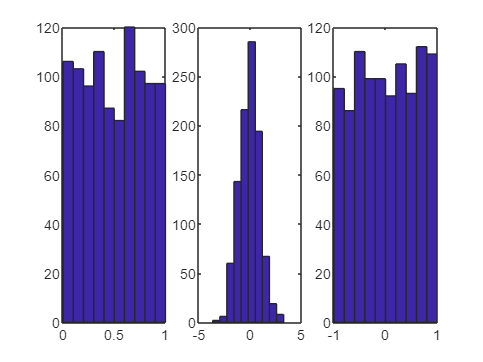

unif_rand = rand(N,1); %[0,1]
norm_rand = randn(N,1); % any real number
unif_rand2 = 2*rand(N,1)-1; %[-1,1]
figure
subplot(1,3,1)
hist(unif_rand)
subplot(1,3,2)
hist(norm_rand)
subplot(1,3,3)
hist(unif_rand2)

How to randomize a vector of demands $d$ with a bounded unifom uncertainty ?

$d'=d+\eta d = (1+\eta) d$ , where $|\eta| < \bar{\eta}$ is the uncertainty

rng(20) % For non-random pseuso-random numbers, use RNG function! Useful for reproducing results.

d = [8 8 6 10 12]

d =      8     8     6    10    12


eta_bar = 0.2 % max uncertainty 20%

eta_bar = 0.2000

eta = (2*rand(1,length(d))-1)*eta_bar.*d

eta =     0.2820    1.2727    0.9397    1.2633   -2.2277


d2 = d + eta

d2 =     8.2820    9.2727    6.9397   11.2633    9.7723


### **Monte Carlo Simulations for EPANET **

How does uncertainty in the base demands, affects the pressures in a network?

Useful for:

- Fault diagnosis

- State estimation

- Forecasting

- Sensitivity studies

- Demonstrating robustness of solutions

**Prepare network for Monte Carlo Simulations**

% Load network
G = epanet('Net2.inp')

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "Net2.inp"...
Input File "Net2.inp" loaded successfully.


G =   epanet with properties:

                                   ph: [1×1 lib.pointer]
                   ControlLevelValues: []
                     ControlLinkIndex: []
                     ControlNodeIndex: []
                         ControlRules: []
                    ControlRulesCount: 0
                             Controls: [1×1 struct]
                      ControlSettings: []
                         ControlTypes: {}
                    ControlTypesIndex: []
                           CurveCount: 0
                           CurveIndex: [1×0 int32]
                           CurvesInfo: [1×1 struct]
                      DemandModelCode: 0
                      DemandModelPmin: 0
                      DemandModelPreq: 0.1000
                      DemandModelPexp: 0.5000
                      DemandModelType: {'DDA'}
                EnergyEfficiencyUnits: 'percent'
                          EnergyUnits: 'kwatt-ho

% Get nominal base demands
base_demands = G.getNodeBaseDemands{1}

base_demands =  -694.4000    8.0000   14.0000    8.0000    8.0000    5.0000    4.0000    9.0000   14.0000    5.0000   34.7800   16.0000    2.0000    2.0000    2.0000   20.0000   20.0000   20.0000    5.0000   19.0000   16.0000   10.0000    8.0000   11.0000    6.0000    8.0000         0    7.0000    3.0000   17.0000   17.0000    1.5000    1.5000         0    1.0000         0


% 5% max uncertainty in base demands
eta_bar = 0.05

eta_bar = 0.0500

**Run the simulation and store the pressure results using parallel processing**

rng(2022) % seed number to always get the same random results
% Number of simulations
Nsim = 50

Nsim = 50

% 5% max uncertainty in base demands
eta_bar = 0.05

eta_bar = 0.0500

% initialize matrix to save MCS pressures
Pmcs = cell(Nsim,1);
for i = 1:Nsim
    %compute new base demands
    delta_bd = (2*rand(1,length(base_demands))-1).*eta_bar.*base_demands;
    new_base_demands = base_demands + delta_bd;
    % Set base demands
    G.setNodeBaseDemands(new_base_demands);
    % Compute pressures at each node
    Pmcs{i} = G.getComputedHydraulicTimeSeries('Pressure');
    disp(['Epoch ',int2str(i)])
end

Epoch 1
Epoch 2
Epoch 3
Epoch 4
Epoch 5
Epoch 6
Epoch 7
Epoch 8
Epoch 9
Epoch 10
Epoch 11
Epoch 12
Epoch 13
Epoch 14
Epoch 15
Epoch 16
Epoch 17
Epoch 18
Epoch 19
Epoch 20
Epoch 21
Epoch 22
Epoch 23
Epoch 24
Epoch 25
Epoch 26
Epoch 27
Epoch 28
Epoch 29
Epoch 30
Epoch 31
Epoch 32
Epoch 33
Epoch 34
Epoch 35
Epoch 36
Epoch 37
Epoch 38
Epoch 39
Epoch 40
Epoch 41
Epoch 42
Epoch 43
Epoch 44
Epoch 45
Epoch 46
Epoch 47
Epoch 48
Epoch 49
Epoch 50


**How pressure fluctuates?**

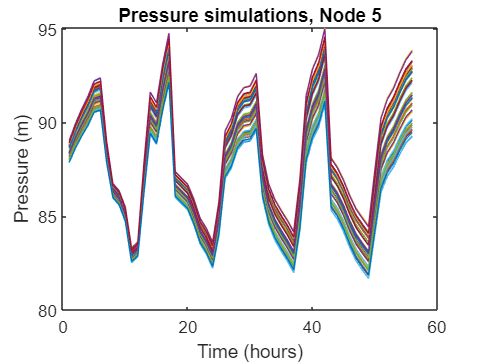

node = 5;
figure
for i = 1:Nsim
    Pmulti(:,i) = Pmcs{i}.Pressure(:,node);
    plot(Pmulti(:,i))
    hold on
end
title(['Pressure simulations, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

**Compute upper and lower bounds**

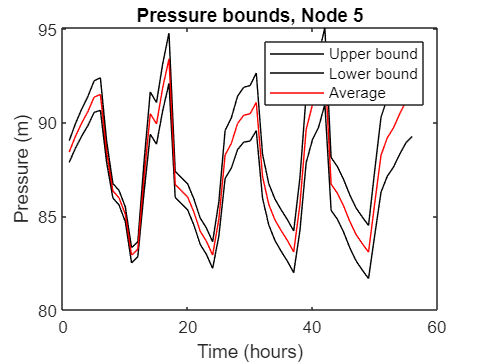

ub = max(Pmulti,[],2);
lb = min(Pmulti,[],2);
meanb = mean(Pmulti,2);

figure
plot(ub,'k')
hold on
plot(lb,'k')
plot(meanb, 'r')
legend('Upper bound','Lower bound', 'Average')
title(['Pressure bounds, Node ',int2str(node)])
xlabel('Time (hours)')
ylabel('Pressure (m)')

## **Exercise: **

Compute how quality fluctuates, compute and plot the intervals.

You can use the *getComputedQualityTimeSeries *function

Store data in Qmcs variable (don't forget to initalize)

% copy code from above and use the function
%Qmcs{i} = G.getComputedQualityTimeSeries.NodeQuality;
% <-- Your code here -->


**How quality fluctuates?**

% node = 5;
% figure
% for i = 1:Nsim
%     Qmulti(:,i) = Qmcs{i}(:,node);
%     plot(Qmulti(:,i))
%     hold on
% end
% title(['Quality simulations, Node ',int2str(node)])
% xlabel('Time (hours)')
% ylabel('Quality (mg/L)')

**Compute upper and lower bounds**

% ub = max(Qmulti,[],2);
% lb = min(Qmulti,[],2);
% meanb = mean(Qmulti,2);
% 
% figure
% plot(ub,'k')
% hold on
% plot(lb,'k')
% plot(meanb, 'r')
% legend('Upper bound','Lower bound', 'Average')
% title(['Quality bounds, Node ',int2str(node)])
% xlabel('Time (hours)')
% ylabel('Pressure (m)')


## **Parallel computations**

Run the simulation and store the pressure results using parallel processing

You need to star the "Parallel Pool" (MATLAB down-left corner for drop-down)

rng(2022)
% Number of simulations
Nsim = 13

Nsim = 13

% 5% max uncertainty in base demands
eta_bar = 0.05

eta_bar = 0.0500

% initialize matrix to save MCS pressures
Pmcs = cell(Nsim,1);
parfor i = 1:Nsim
    G(i) = epanet('Net2.inp','ph')
    % Get nominal base demands
    base_demands = G(i).getNodeBaseDemands{1}
    %compute new base demands
    delta_bd = (2*rand(1,length(base_demands))-1).*eta_bar.*base_demands;
    new_base_demands = base_demands + delta_bd;
    % Set base demands
    G(i).setNodeBaseDemands(new_base_demands);
    % Compute pressure and node quality
    Pmcs{i} = G(i).getComputedHydraulicTimeSeries.Pressure;
    %Qmcs{i} = G.getComputedQualityTimeSeries.NodeQuality;
    disp(['Epoch ',int2str(i)])
end

EPANET version {20200} loaded (EMT version {v2.2.1}).
> In epanet/saveInputFile (line 13192)
In epanet (

Error using epanet/saveInputFile
The process cannot access the file because it is being used by another process.


Error in epanet (line 4129)
                obj.saveInputFile(obj.BinTempfile); %create a new INP file (Working Copy) using the SAVE command of EPANET